## Лаба 6. Критерий Найквиста и системы с запаздыванием

### Задание 1. Годограф Найквиста

p = 1; q = 4; n = 4; m = 1;
count = 1;

% a0 = 1; a1 = 1; a2 = 1; a3 = 1; a4 = 1;      a5 = 1;
% b0 = 1; b1 = 1; b2 = 1; b3 = 1; b4 = 1;      b5 = 1;

### Объект 1

lambda1 = -1; lambda2 = -1;lambda3 = -1;    lambda4 = -1; lambda5 = 10;
gamma = -1; alpha1 = 0.2; alpha2 = 1.5; beta1 = 1.8; beta2 = 0.5;
s = tf('p');

W_open = ( (s-lambda1)*(s-lambda2)*(s-lambda3)*(s-lambda4)*(s-lambda5) ) / ((s-gamma)*((s-alpha1)^2 + beta1^2)*((s-alpha2)^2 + beta2^2));

In result of some kind research with my teacher & mentor, matlab do not alway interpreter this...

% W_closed = 1 / (W_open+1);

As right closed system, so i offer you to use

W_closed = feedback(W_open, 1);

instead.

% W_open_closed = ((s-lambda1)*(s-lambda2)*(s-lambda3)*(s-lambda4)*(s-lambda5)) / ...
%           ((s-lambda1)*(s-lambda2)*(s-lambda3)*(s-lambda4)*(s-lambda5) + ((s-gamma)*((s-alpha1)^2 + beta1^2)*((s-alpha2)^2 + beta2^2)));

syms x

expand((x-lambda1)*(x-lambda2)*(x-lambda3)*(x-lambda4)*(x-lambda5))

$$ans = x^{5}-6\,x^{4}-34\,x^{3}-56\,x^{2}-39\,x-10$$

expand((x-gamma)*((x-alpha1)^2 + beta1^2)*((x-alpha2)^2 + beta2^2))

$$ans = x^{5}-\frac{12\,x^{4}}{5}+\frac{179\,x^{3}}{50}-\frac{193\,x^{2}}{50}-\frac{66\,x}{25}+\frac{41}{5}$$

expand( ((x-lambda1)*(x-lambda2)*(x-lambda3)*(x-lambda4)*(x-lambda5) + ((x-gamma)*((x-alpha1)^2 + beta1^2)*((x-alpha2)^2 + beta2^2))))

$$ans = 2\,x^{5}-\frac{42\,x^{4}}{5}-\frac{1521\,x^{3}}{50}-\frac{2993\,x^{2}}{50}-\frac{1041\,x}{25}-\frac{9}{5}$$


ans1 = solve( ((x-lambda1)*(x-lambda2)*(x-lambda3)*(x-lambda4)*(x-lambda5) + ((x-gamma)*((x-alpha1)^2 + beta1^2)*((x-alpha2)^2 + beta2^2))), x);
roots_closed = double(vpa(ans1))

roots_closed =   -1.0000 + 0.0000i
  -0.0462 + 0.0000i
  -0.8917 - 1.4051i
  -0.8917 + 1.4051i
   7.0297 + 0.0000i


ans2 = solve( (x-gamma)*((x-alpha1)^2 + beta1^2)*((x-alpha2)^2 + beta2^2), x);
roots_open = double(vpa(ans2))

roots_open =   -1.0000 + 0.0000i
   0.2000 - 1.8000i
   0.2000 + 1.8000i
   1.5000 - 0.5000i
   1.5000 + 0.5000i


### Объект 1 - разомкнутая система

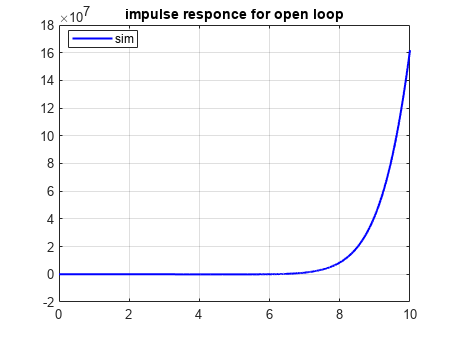

simTimeStart = 0;
simTimeEnd = 10;
dt = 0.002;
t_sim = simTimeStart:dt:simTimeEnd;
% Impulse&&Step applied at t=0
%%% ТЕОР-АНАЛ весовые функции %%%
figure;
[y_sim, t_out] = impulse(W_open, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
legend('sim', 'Location', 'best')
title('impulse responce for open loop')
hold off
save_file("impulse_responce_open"+count);

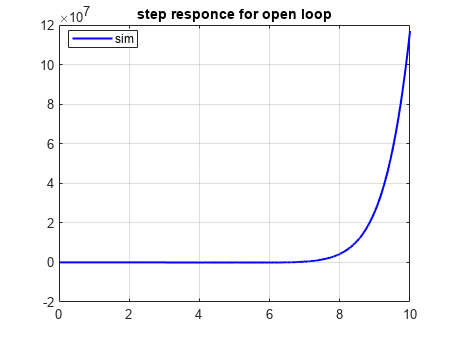

%%% ТЕОР-АНАЛ переходные функции %%%
figure;
[y_sim, t_out] = step(W_open, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for open loop')
legend('sim', 'Location', 'best')
save_file("step_responce_open"+count);

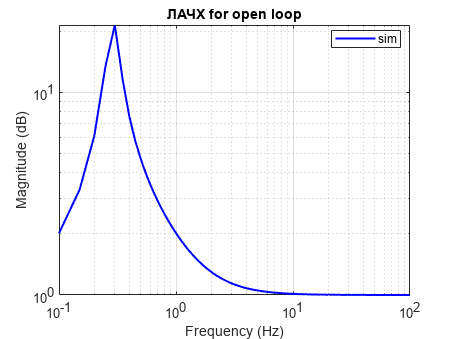

%%% ЛАЧХ-ЛФЧХ %%%
freqs = linspace(0.1, 100, 2000);
omega = 2*pi*freqs;
[mag, phase, ~] = bode(W_open, omega); % omega is in rad/s
mag = squeeze(mag); % Magnitude (absolute, not dB)
phase = squeeze(phase); % Phase (degrees)

figure;
loglog(freqs, mag, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
title('ЛАЧХ for open loop')
legend('sim', 'Location', 'best')
save_file("lfreq_ampl_open"+count);

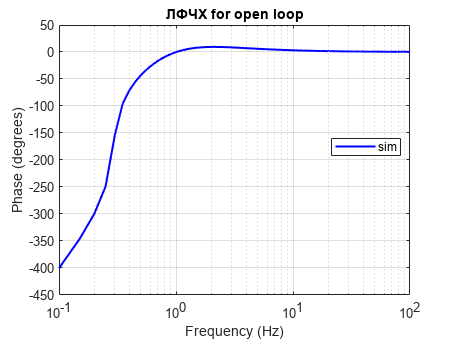


figure;
semilogx(freqs, phase, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;
title('ЛФЧХ for open loop')
legend('sim', 'Location', 'best')
save_file("lfreq_phase_open"+count);

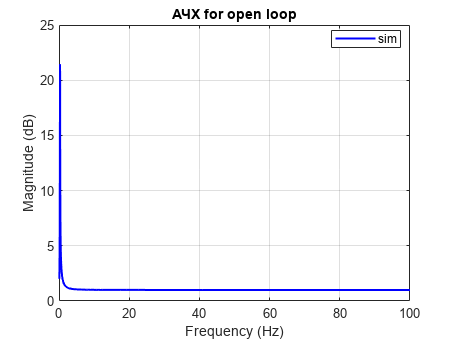


%%% АЧХ-ФЧХ %%%
figure;
plot(freqs, mag, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
title('АЧХ for open loop')
legend('sim', 'Location', 'best')
save_file("freq_ampl_open"+count);

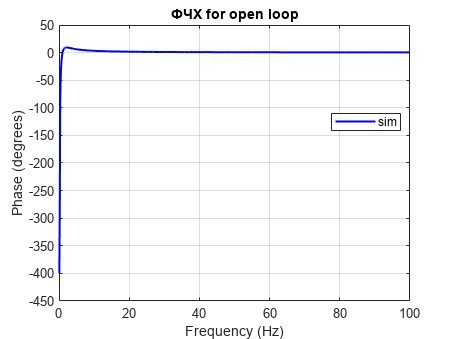


figure;
plot(freqs, phase, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
title('ФЧХ for open loop')
grid on;
legend('sim', 'Location', 'best')
save_file("freq_phase_open"+count);

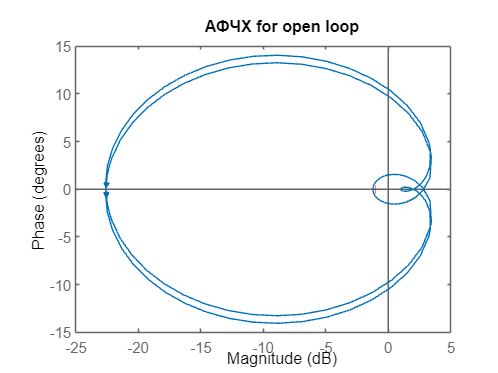


%%% АФЧХ %%%
figure;
nyquistplot(W_open)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title('АФЧХ for open loop')
save_file("nyquistplot_open"+count);

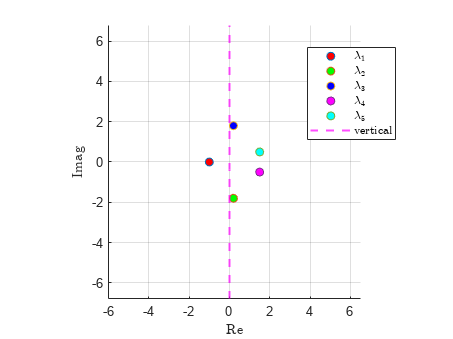


plotComplexRoots(roots_open);
save_file("roots_open"+count);

### Объект 1 - замкнутая система

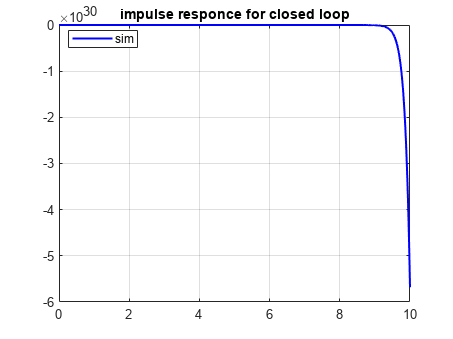

% Impulse&&Step applied at t=0
%%% ТЕОР-АНАЛ весовые функции %%%
figure;
[y_sim, t_out] = impulse(W_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
legend('sim', 'Location', 'best')
hold off
title('impulse responce for closed loop')
save_file("impulse_responce_closed"+count);

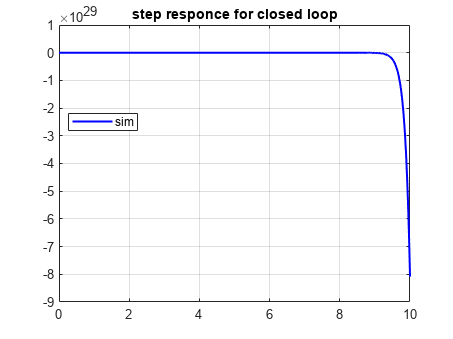

%%% ТЕОР-АНАЛ переходные функции %%%
figure;
[y_sim, t_out] = step(W_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
legend('sim', 'Location', 'best')
title('step responce for closed loop')
save_file("step_responce_closed"+count);

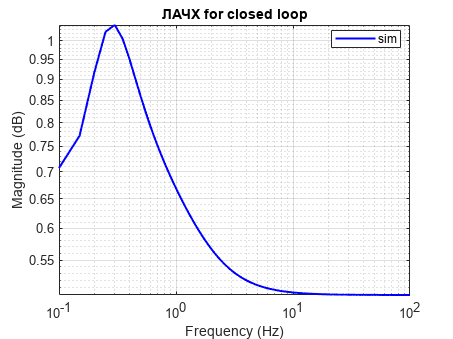

%%% ЛАЧХ-ЛФЧХ %%%
freqs = linspace(0.1, 100, 2000);
omega = 2*pi*freqs;
[mag, phase, ~] = bode(W_closed, omega); % omega is in rad/s
mag = squeeze(mag); % Magnitude (absolute, not dB)
phase = squeeze(phase); % Phase (degrees)

figure;
loglog(freqs, mag, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
legend('sim', 'Location', 'best')
title('ЛАЧХ for closed loop')
save_file("lfreq_ampl_closed"+count);

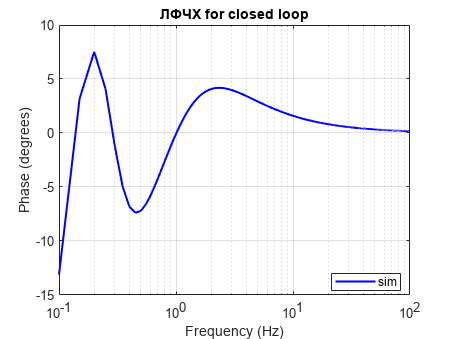


figure;
semilogx(freqs, phase, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;
title('ЛФЧХ for closed loop')
legend('sim', 'Location', 'best')
save_file("lfreq_phase_closed"+count);

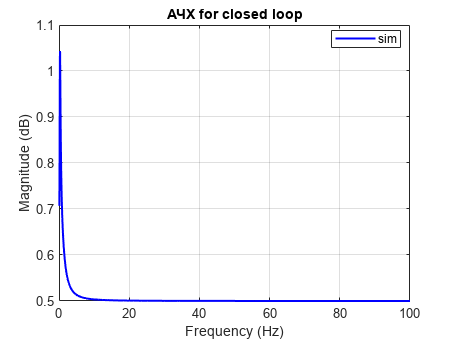


%%% АЧХ-ФЧХ %%%
figure;
plot(freqs, mag, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
title('АЧХ for closed loop')
legend('sim', 'Location', 'best')
save_file("freq_ampl_closed"+count);

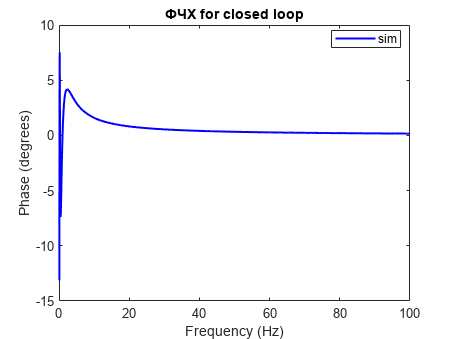


figure;
plot(freqs, phase, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
title('ЛАЧХ for closed loop')
% grid on;
title('ФЧХ for closed loop')
legend('sim', 'Location', 'best')
save_file("freq_phase_closed"+count);

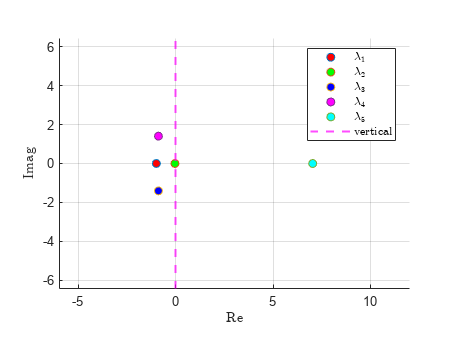


plotComplexRoots(roots_closed);
save_file("roots_closed"+count);

% helped for old matlab versions -
% https://www.mathworks.com/matlabcentral/answers/136462-how-can-you-turn-on-all-stability-margins-when-using-the-bode-function-via-script
figure;
h = bodeplot(W_open)


h =

	resppack.bodeplot



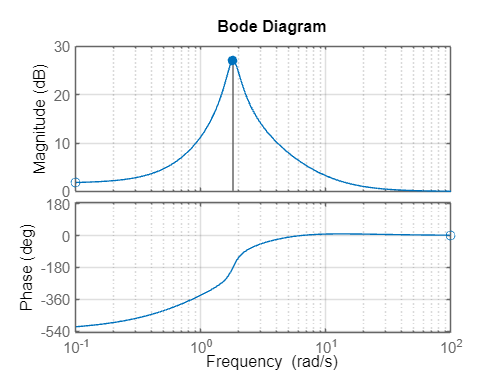

grid on;
h.showCharacteristic('AllStabilityMargins');
save_file("log_nyquist"+count);

## Функции

**Save file in the folder**

function save_file(name)
    path = 'D:\Math\control_theory\linear_systems_labs\lab6\latex6\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');
end

**Рисовать комплексные числа**

function plotComplexRoots(roots)
    % Input: 'roots' is a vector containing up to 5 complex numbers.
    
    % Ensure the figure is properly configured
    figure;
    hold on;
    grid on;
    axis equal;
    title(' ');
    xlabel('Re', 'Interpreter', 'latex');
    ylabel('Imag', 'Interpreter', 'latex');
    
    % Define colors for up to 5 roots
    colors = {'r', 'g', 'b', 'm', 'c'};
    
    % Plot each root with unique color and LaTeX label
    for i = 1:min(length(roots), 5)
        plot(real(roots(i)), imag(roots(i)), 'o', ...
            'MarkerSize', 6, 'MarkerFaceColor', colors{i}, ...
            'DisplayName', ['$\lambda_' num2str(i) '$']);
    end
    
    % Compute limits with offset for better visibility
    real_vals = real(roots);
    imag_vals = imag(roots);
    real_min = min(real_vals) - 5;
    real_max = max(real_vals) + 5;
    imag_min = min(imag_vals) - 5;
    imag_max = max(imag_vals) + 5;
    
    % Set axis limits
    xlim([real_min, real_max]);
    ylim([imag_min, imag_max]);
    
    % Add a vertical magenta line at x = 0
    xline(0, 'm--', 'LineWidth', 1.5, 'DisplayName','vertical');
    
    % Add a legend with LaTeX interpreter
    legend('Interpreter', 'latex', 'Location', 'best');
    
    hold off;
end

% 
% simTimeStart = 0;
% simTimeEnd = 5;
% 
% l1 = -2 + 3j; l2 = -2 - 3j; l3= -10;
% out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
% t = out.simout.Time;
% y_out = out.simout.Data; g_show = ones(1, length(t))'; 
% 
% h = figure; set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% subplot(2,1,1);
% plot(t, y_out, 'r');
% title('output');   
% xlabel('time [s]');                  
% ylabel('f(t)');                      
% grid on;
% legend('y(t)');
% 
% subplot(2,1,2);
% plotComplex(l1,l2,l3)
% save_file(h, 'output_task2_exp12')
% 
% % Вычисление стационарного значения
% y_final = y_out(end);
% % перерегулирование по стандартной формуле
% y_max = max(y_out);
% overshoot = ((y_max - y_final) / y_final) * 100
% % Время, когда функция достигает 98% от конечного значения
% threshold = 0.99 * y_final; 
% transient_time = t( find(y_out >= threshold, 1) )